filename = './summers2016convex_greedy.txt';
startRow = 10;

formatSpec = '%*1s%9f%f%[^\n\r]';

fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');

fclose(fileID);

summers_greedy = table(dataArray{1:end-1}, 'VariableNames', {'X','Y'})

summers_greedy = 10×2 table
        X             Y     
    __________    __________

    3.9920e+01    6.9530e-01
    6.0300e+01    5.1980e-01
    7.9790e+01    2.1000e+00
    9.9980e+01    4.3820e+00
    1.2020e+02    8.5940e+00
    1.4040e+02    1.9650e+01
    1.5990e+02    3.4570e+01
    1.8000e+02    5.7570e+01
    2.0030e+02    8.9340e+01
    2.5040e+02    2.2990e+02



clearvars filename startRow formatSpec fileID dataArray ans;

filename = './summers2016convex_sdp.txt';
startRow = 10;

formatSpec = '%*1s%9f%f%[^\n\r]';

fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');

fclose(fileID);

summers_sdp = table(dataArray{1:end-1}, 'VariableNames', {'X','Y'})

summers_sdp = 5×2 table
        X             Y     
    __________    __________

    3.9920e+01    2.1000e+00
    6.0200e+01    7.1900e+00
    7.9890e+01    3.8260e+01
    9.9980e+01    1.2010e+02
    1.2020e+02    3.1000e+02



clearvars filename startRow formatSpec fileID dataArray ans;

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; 
LW = 'LineWidth'; FN = 'FontName'; TN = 'Times New Roman'; DN = 'DisplayName';

stmp = "n";

figtmp = figure();

xtmp = summers_sdp.X; ytmp = summers_sdp.Y;
l2 = loglog(xtmp,ytmp,'x',DN,"SDP","Color",[0.68, 0.00, 0.31],MS,10,LW,2);

hold on
xtmp = summers_greedy.X; ytmp = summers_greedy.Y; 
l1 = loglog(xtmp,ytmp,'o',DN,"Greedy",'Color',[0.25, 0.62, 0.25],MS,10,LW,2);

xc = xtmp(fix(end/2+1));
yc = ytmp(fix(end/2+1))

yc =    1.9650e+01



% loglog(summers_greedy.X,((summers_greedy.X).^5)*9e-10,DN,"n^5")
% loglog(summers_greedy.X,((summers_greedy.X).^4)*9e-10,DN,"n^4")
strtmp = string(sprintf('{\\it%s}^{5}', stmp));
loglog(xtmp,((xtmp).^5)*yc/xc.^5,DN,[strtmp{:}])
strtmp = string(sprintf('{\\it%s}^{6}', stmp));
loglog(xtmp,((xtmp).^6)*yc/xc.^6,DN,[strtmp{:}])
% loglog(summers_greedy.X,((summers_greedy.X).^5)*5e-10,"Color",l1.Color,"DisplayName","Greedy")
% loglog(summers_greedy.X,((summers_greedy.X).^5)*5e-9,"Color",l2.Color)

hold off

legend('Location','southeast')

ax1 = gca(figtmp)

ax1 =   Axes のプロパティ:

             XLim: [3.9920e+01 2.5040e+02]
             YLim: [1.0000e-02 1000]
           XScale: 'log'
           YScale: 'log'
    GridLineStyle: '-'
         Position: [1.3000e-01 1.1000e-01 7.7500e-01 8.1500e-01]
            Units: 'normalized'

  すべてのプロパティ を表示


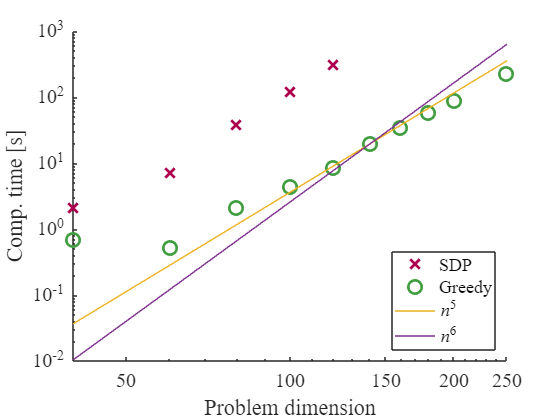

ax1.Box = 'off';
ax1.Color = 'none';
set(ax1,FS,15,FN,'Times New Roman');
ylabel(ax1,'Comp. time [s]');
xlabel(ax1,'Problem dimension');